%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                FMCW Radar Simulator               %
%                                                   %
% Author: Lin Junyang                               %
% Email : linjy@163.com                             %
% Date  : 2019-6-15                                 %
%                                                   %
% All Rights Reserved.                              %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% A simulatior of 1 TX antena and 2 RX antena FMCW radar.
% Simulation of close handwave movement: Left - Right

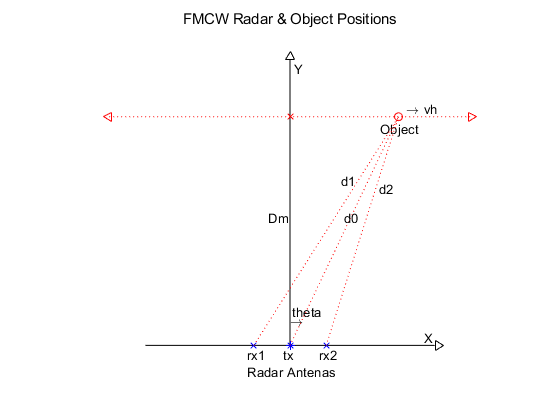

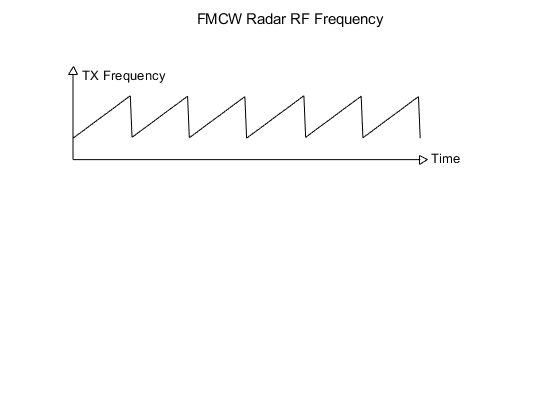

radar_simulation_plot_basis

SimulationTime = 3;                     % simulation time seconds
SampleRate = 2e6;                       % 2MHz radar data sample rate
dt = 1/SampleRate;                      % data point interval
ChirpPeriod = 1e-3;                     % 1ms
ChirpNum = SimulationTime/ChirpPeriod;  % number of chirps
N = SimulationTime*SampleRate;          % data points for simulation
n = 1:N;                                % data points indexes
t = (n-1)*dt;                           % time

c = 3e8;                % speed of light
B = 4e9;                % radar band
S = B/ChirpPeriod;      % radar parameter, band slope 4GHz/ms
Dres = c/2/B;           % distance resolution
Lamda = 0.012;          % radar parameter, 12mm lamda
Dx = 2*(Lamda/2);       % rx1 rx2 distance
Dm = 1.8*Dres;           % 8cm, distance vertical

x0 = 0;                 % tx position x
y0 = 0;                 % tx position y
x1 = -Dx/2;             % rx1 position x
y1 = 0;                 % rx1 position y
x2 = Dx/2;              % rx2 position x
y2 = 0;                 % rx2 position y

vh = 2.5*cos(6*t);        % simulation of close handwave movement
% figure;title('vh');plot(vh)

y = Dm;                 % Object horizential distance from radar
x = zeros(1,N);         % Object x postion

x(1) = 0;
for k = 2:N
    x(k) = x(k-1) + vh(k-1)*dt;
end
% figure;title('Object X postion');plot(x)

theta = -atan(x/y);
vr = vh.*sin(theta);
vt = vh.*cos(theta);
% figure;hold on;title('theta,vr,vt');plot(theta);plot(vr);plot(vt)

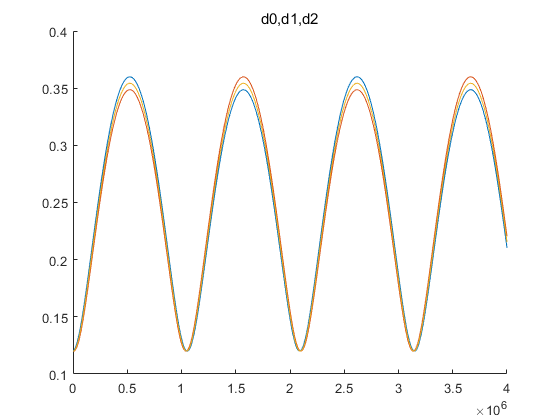

d0 = ((x-x0).^2 + (y-y0).^2).^0.5;
d1 = ((x-x1).^2 + (y-y1).^2).^0.5;
d2 = ((x-x2).^2 + (y-y2).^2).^0.5;
% figure;title('d0,d1,d2');hold on;plot(d1);plot(d2);plot(d0)

if1 = S*(d0+d1)/c;
if2 = S*(d0+d2)/c;

w1 = 2*pi*if1;
w2 = 2*pi*if2;

% figure;title('if_w1,if_w2');hold on;plot(w1);plot(w2);

tx_f = 23.5e9 + mod(t,ChirpPeriod)*S;
% figure; title('tx_f');plot(tx_f(1:100000))

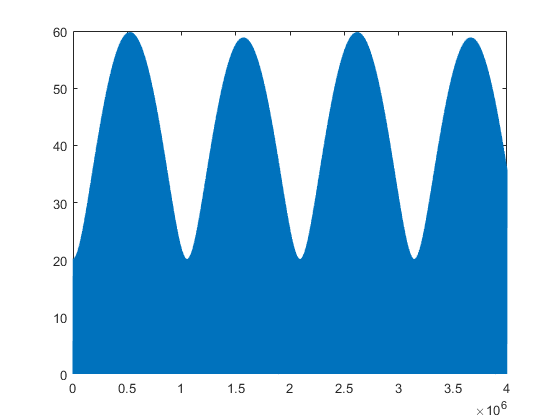

ChirpDataLen = ChirpPeriod*SampleRate;

rx1_wt_phi = zeros(1,N);
rx2_wt_phi = zeros(1,N);

for k = 1:N
    if mod(k,ChirpDataLen)==1
        rx1_wt_phi(k) = 0;
        rx2_wt_phi(k) = 0;
    else
        rx1_wt_phi(k) = rx1_wt_phi(k-1)+w1(k-1)*dt;
        rx2_wt_phi(k) = rx2_wt_phi(k-1)+w2(k-1)*dt;
    end
end
% figure; title('w1_phi');plot(rx1_wt_phi)

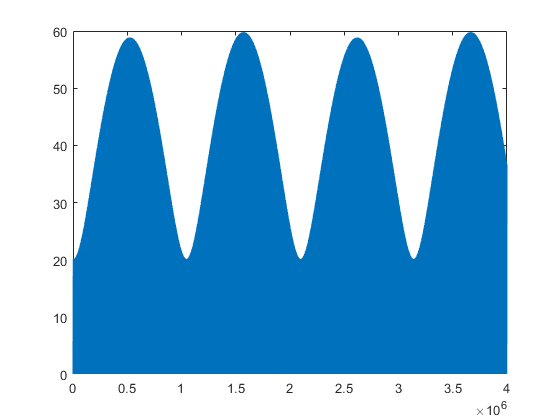

% figure; title('w2_phi'); plot(rx2_wt_phi)

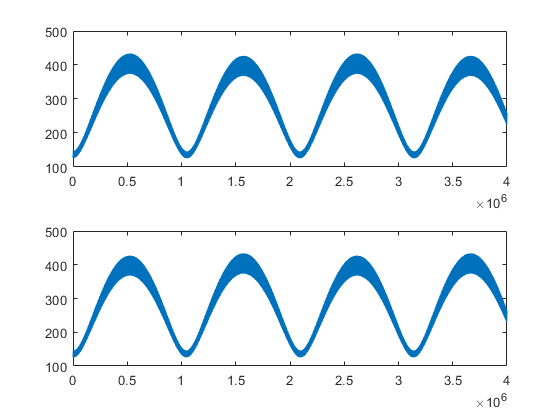

rx1_phi = rx1_wt_phi + (d0+d1)*2*pi/Lamda;
rx2_phi = rx2_wt_phi + (d0+d2)*2*pi/Lamda;

% figure; 
% subplot(2,1,1)
% plot(rx1_phi)
% subplot(2,1,2)
% plot(rx2_phi)

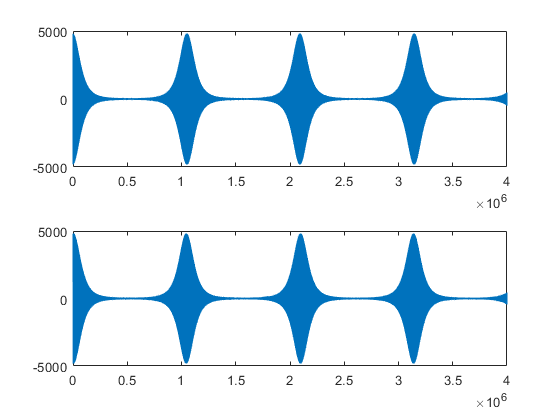


rx1 = exp(rx1_phi*1j)./d0.^2./d1.^2;
rx2 = exp(rx2_phi*1j)./d0.^2./d2.^2;

% figure;
% subplot(2,1,1)
% plot(real(rx1))
% subplot(2,1,2)
% plot(real(rx2))

RX1_I = real(rx1);
RX1_Q = imag(rx1);
RX2_I = real(rx2);
RX2_Q = imag(rx2);

RX1_CHIRPS_I = zeros(ChirpNum,ChirpDataLen);
RX1_CHIRPS_Q = zeros(ChirpNum,ChirpDataLen);
RX2_CHIRPS_I = zeros(ChirpNum,ChirpDataLen);
RX2_CHIRPS_Q = zeros(ChirpNum,ChirpDataLen);

for k = 1:ChirpNum
    chirp_start = (k-1)*ChirpDataLen + 1;
    chirp_end = k*ChirpDataLen;
    RX1_CHIRPS_I(k,:) = RX1_I(chirp_start:chirp_end);
    RX1_CHIRPS_Q(k,:) = RX1_Q(chirp_start:chirp_end);
    RX2_CHIRPS_I(k,:) = RX2_I(chirp_start:chirp_end);
    RX2_CHIRPS_Q(k,:) = RX2_Q(chirp_start:chirp_end);
    
    % Radar chip TX amplitude modulation
    for m=1:ChirpDataLen
        RX1_CHIRPS_I(k,m) = RX1_CHIRPS_I(k,m)*(m/ChirpDataLen)^0.33;
        RX1_CHIRPS_Q(k,m) = RX1_CHIRPS_Q(k,m)*(m/ChirpDataLen)^0.33;
        RX2_CHIRPS_I(k,m) = RX2_CHIRPS_I(k,m)*(m/ChirpDataLen)^0.33;
        RX2_CHIRPS_Q(k,m) = RX2_CHIRPS_Q(k,m)*(m/ChirpDataLen)^0.33;
    end
end

RX1_CHIRPS_I = RX1_CHIRPS_I(:,1:1360);
RX1_CHIRPS_Q = RX1_CHIRPS_Q(:,1:1360);
RX2_CHIRPS_I = RX2_CHIRPS_I(:,1:1360);
RX2_CHIRPS_Q = RX2_CHIRPS_Q(:,1:1360);

% Add random noise
NoiseAmp = 0.3;
RX1_CHIRPS_I = RX1_CHIRPS_I + rand(size(RX1_CHIRPS_I))*NoiseAmp;
RX1_CHIRPS_Q = RX1_CHIRPS_Q + rand(size(RX1_CHIRPS_Q))*NoiseAmp;
RX2_CHIRPS_I = RX2_CHIRPS_I + rand(size(RX2_CHIRPS_I))*NoiseAmp;
RX2_CHIRPS_Q = RX2_CHIRPS_Q + rand(size(RX2_CHIRPS_Q))*NoiseAmp;


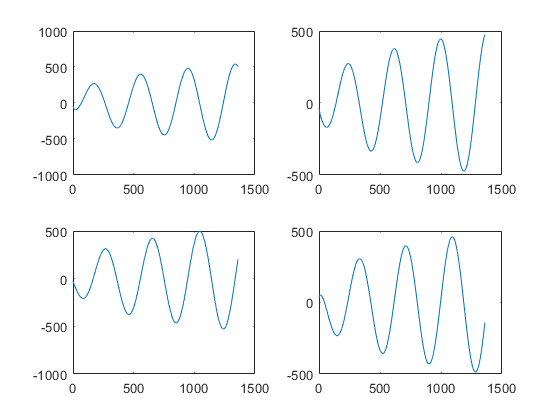

% chirp_sample_idx = randi(ChirpNum);
% figure; 
% title(['Chirp sample index: ',num2str(chirp_sample_idx)])
% subplot(2,2,1);plot(RX1_CHIRPS_I(chirp_sample_idx,:))
% subplot(2,2,2);plot(RX2_CHIRPS_I(chirp_sample_idx,:))
% subplot(2,2,3);plot(RX1_CHIRPS_Q(chirp_sample_idx,:))
% subplot(2,2,4);plot(RX2_CHIRPS_Q(chirp_sample_idx,:))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FMCW Radar Simulation Outputs are:                %
%       RX1_CHIRPS_I                                %
%       RX1_CHIRPS_Q                                %
%       RX2_CHIRPS_I                                %
%       RX2_CHIRPS_Q                                %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%